# Example 3: Simulations of Travel and Residence Times in a Binary Hydraulic Conductivity Field

## Introduction

This is another demonstration problem from [[1](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)], used to test the Double Delineation Approach (DDA). It simulates diagonally oriented groundwater flow between an injection well and a pumping well, positioned at the lower left and upper right corners of a binary hydraulic conductivity field composed of randomly distributed permeable and less permeable materials.

We begin by clearing all variables in the workspace and then loading the relevant length and time constant units.

clear;                              
setLengthUnitsInWorkspace();        
setTimeUnitsInWorkspace(2024);

## Set up Simulation Data

Let's create a 100-by-100-by-1 uniform grid with a cell size of 1 meter in all directions. 

Grid = cartGrid(0:1:100, 0:1:100, 0:1:1); 

Load a MAT file (i.e., *dual_K.mat*) containing the distributed hydraulic conductivity values, represented as a 100-by-100 matrix. The map includes only two values: 1 meter per day for the more permeable zones and 0.001 meters per day for the less permeable zones. 

load('dual_K.mat');

% Define cell-wise hydraulic conductivity & porosity
K = reshape(dual_K, [Grid.Nx, Grid.Ny, Grid.Nz]) / day;
Grid.properties.hydraulic_conductivity = ones(3, Grid.Nx, Grid.Ny, Grid.Nz);
for i = 1:3
   Grid.properties.hydraulic_conductivity (i,:,:,:) = K;
end
Grid.properties.porosity = 0.25*ones(Grid.Nx,Grid.Ny,Grid.Nz);

Set the pumping and injection flow rates to 20 cubic meters per hour. 

Q = 20 * meter^3/hour; 

Add an injection well at the lower left corner grid cell and a pumping (abstraction) well at the upper right corner grid cell.

W = verticalWell([], Grid, 1, 1, 1, Q, 'type', 'injection', 'name', 'I');
W = verticalWell(W, Grid, 100, 100, 1, Q, 'type', 'pumping', 'name', 'P');

Finally, construct a two-dimensional grid analog for planar visualization tasks.

G2D = cartGrid(0:1:100, 0:1:100);

## Groundwater Flow and Travel Times Simulations

Run the groundwater flow model, followed by forward and backward travel time simulations to quantify cell-wise travel time values.

% Simulate hydraulic heads in the aquifer
tic, [h,V] = head(Grid, W); toc

Number of PCG iterations = 157
Residual norm error      = 8.95975E-07
Elapsed time is 0.131785 seconds.



% Travel time simulations
ftt = travelTime(Grid, V, W, true);
btt = travelTime(Grid, V, W, false);

% Convert to days unit
ftt = ftt/day; btt = btt/day;

% Calculate residence time 
rt = ftt + btt;

## Flow Visualization using Streamlines

Here, we display the binary hydraulic conductivity map as the background of the plot. Next, 21 particles are placed near the injection well. A particle tracking simulation is then conducted using a numerical integration approach, revealing the primary conductive channels in the flow field.    

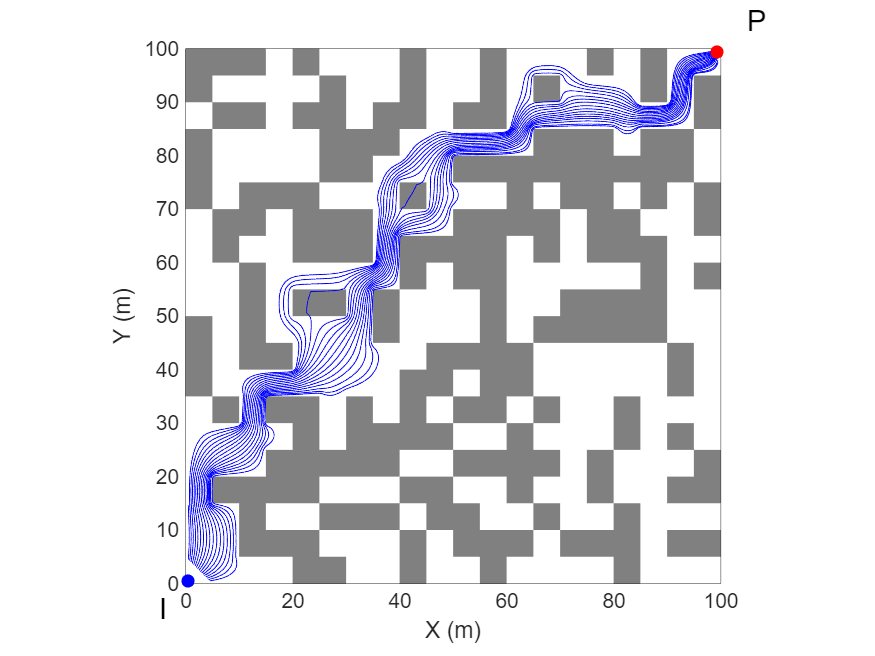

%--- First, plot the binary hydraulic conductivity map on the background
figure; 
colormap([0.5 0.5 0.5; 1 1 1]);
plotCellData(G2D,reshape(dual_K,[100*100,1]),'EdgeColor','none');
colorbar off;
hold on; 

%--- block to plot streamlines
coords = zeros(2,21);                        % initialize particles coordinates 
coords(1,:) = 0:.25:5;                       % x-coordinates of the particles
coords(2,:) = 5:-.25:0;                      % y-coordinates of the particles
plotStreamline(V, [Grid.hx Grid.hy], coords, true, 'Color', 'b', 'LineWidth', 0.5);

%--- Plot decoration (wells positions and names, etc.)
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
axis tight equal;
xlabel('X (m)'); ylabel('Y (m)');
box on,
hold off;

The results indicate that the fastest flow paths between the two wells are primarily connected through diagonally oriented channels, which occasionally shift direction to avoid obstacles in the flow. However, this provides only a partial view of all possible flow paths that could connect the two wells. This limitation arises from the particle tracking approach, as the simulated flow paths are highly dependent on the initial positions of the tracked particles.

Now, we will simulate multiple streamlines to ensure that the traced flow lines cover, as extensively as possible, all areas of the computational domain. To achieve this, we will evenly distribute approximately 100 particles at the diagonal opposite of the line connecting the two wells. Next, we will trace the streamlines in both the direction of the flow field and the reverse direction. 

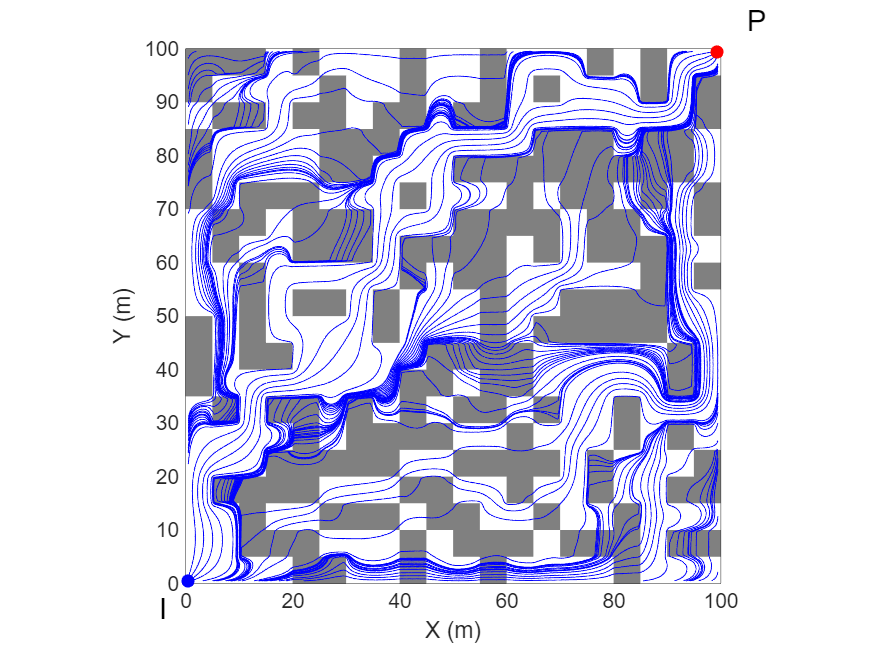

figure; 
colormap([0.5 0.5 0.5; 1 1 1]);
plotCellData(G2D,reshape(dual_K,[100*100,1]),'EdgeColor','none');
colorbar off;
hold on; 

%--- block to plot streamlines
coords = zeros(2,101);                       % initialize particles coordinates 
coords(1,:) = 0:1:100;                       % x-coordinates of the particles
coords(2,:) = 100*ones(1,101)-coords(1,:);   % y-coordinates of the particles
plotStreamline(V, [Grid.hx Grid.hy], coords, true,  'Color', 'b', 'LineWidth', 0.5);
plotStreamline(V, [Grid.hx Grid.hy], coords, false, 'Color', 'b', 'LineWidth', 0.5);

%--- Plot decoration (wells positions and names, etc.)
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
axis tight equal;
xlabel('X (m)'); ylabel('Y (m)');
box on,
hold off;

The particle tracing results reveal the presence of additional channels connecting the two wells, each corresponding to different residence times in the aquifer. Notably, areas with high flow density indicate proportionally higher circulating flow rates. This is a valuable aspect of visualizing flow fields using streamlines. However, it is important to note that there are still grid cells in the domain that are not intersected by any particle paths. Therefore, the particle tracking method is not intended to provide a comprehensive overview of travel times (or residence times) at every position in the aquifer.

Furthermore, this example illustrates that obtaining a comprehensive view of flow field connectivity using particle tracking is inherently an iterative process, even in this basic configuration involving a simple rectangular two-dimensional box with one source and one sink. For field-scale applications, particularly in three-dimensional cases, this task becomes more complex, and the results are more difficult to interpret. This is why the Double Delineation Approach (DDA) serves as a valuable alternative.

## Flow Visualization using the Double Delineation Approach 

First, we plot the distribution of hydraulic heads in the background, overlaid with the residence time iso-contour at 10 days, which represents the trajectories that take 10 days to travel between the wells.   

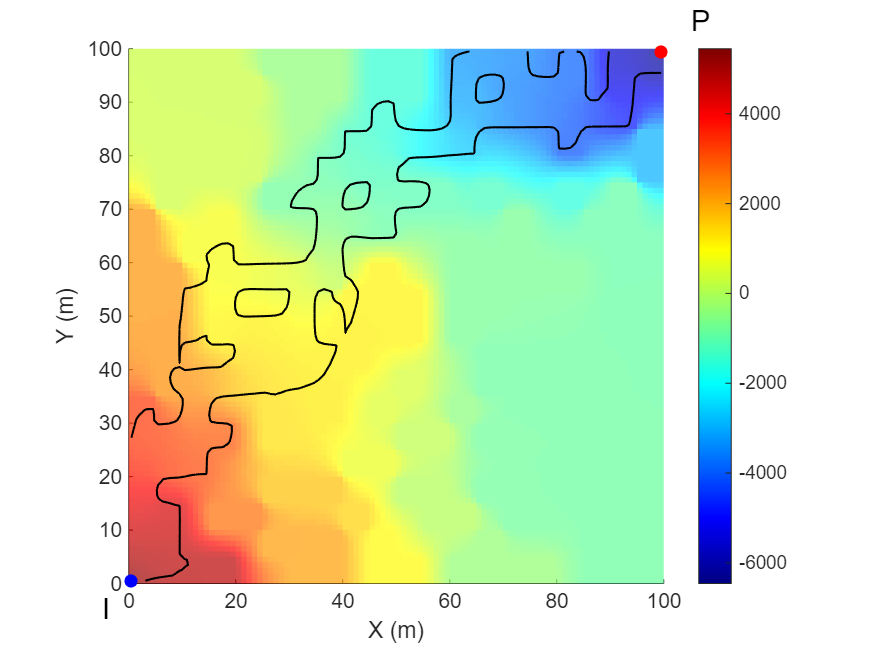

figure; 
colormap(jet);
plotCellData(G2D,h(:),'FaceAlpha', 0.7, 'EdgeColor', 'none');
hold on;

%--- Draw iso-contours of the residence time with blue color 
[M,~] = plotContourData(G2D,rt,opts,...
    'LevelList',10,...
    'LineStyle','-',...
    'LineWidth',1,...
    'LineColor','k');

scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);

%--- 
axis tight equal; 
xlabel('X (m)'); ylabel('Y (m)');
colorbar;
hold off;

In addition to the two lines connecting the wells, the figure displays internal closed loops as iso-values at this residence time level. These structures are characteristic of heterogeneous systems, where groundwater within less permeable materials experiences a longer residence time. As a result, a sharp gradient of this variable is observed at the interfaces separating materials with significant contrasts in hydraulic conductivity. 

Here, we plot classes of forward travel time in days, ranging from 0 to 10 days in intervals of 1 day. Each class is represented by a different color in the jet colormap. 

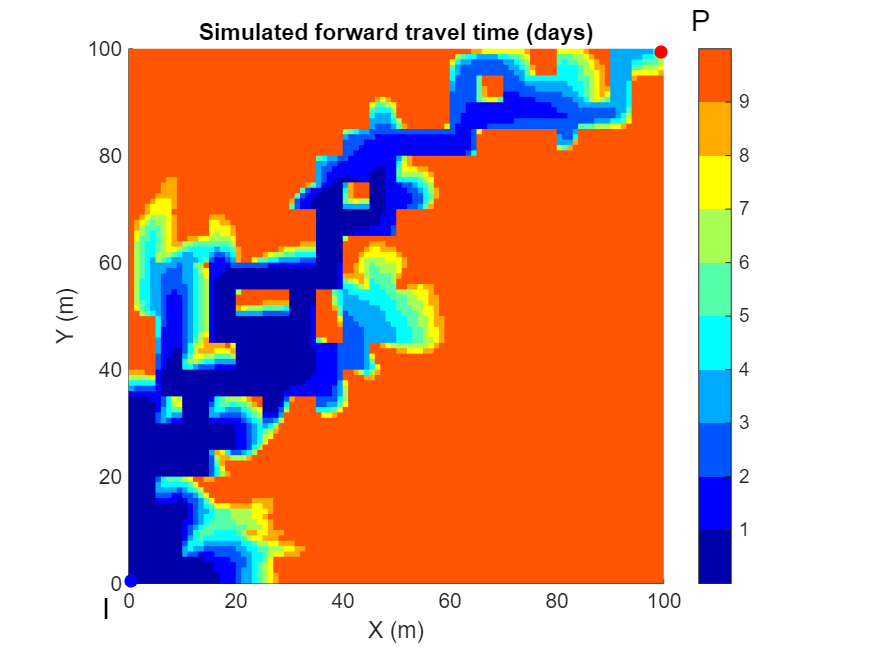

figure; 
var = ftt;
var(var > 10) = nan;
colormap(jet(10));
plotCellData(G2D,var,'EdgeColor','none');
colorbar;
axis([0 100 0 100]); 
xticks(0:20:100);
yticks(0:20:100);
axis equal tight;
title('Simulated forward travel time (days)'); 
xlabel('X (m)'); ylabel('Y (m)');
hold on; 
scatter(0.5,0.5,40,"blue","filled");
scatter(99.5,99.5,40,"red","filled");
text([-5,105], [-5,105], {'I','P'}, 'FontSize', 14);
hold off;

Another effective way to visualize travel times, particularly residence time, in aquifer systems is to apply a log10 transformation to this variable. This approach is useful because residence times can vary across many orders of magnitude in aquifer systems, whether they are local, intermediate, or regional scale models. 

Here, we utilize a scaled index introduced in [[2](https://www.researchgate.net/publication/331903631_Automatic_Generation_of_Locally_Refined_Composite_Grids_for_Efficient_Solute_Transport_Modeling)], which is designed to identify aquifer regions based on logarithmic magnitudes of travel times. This leads to a hierarchy of aquifer pore volumes corresponding to the magnitude of specific discharge. This index is beneficial for various tasks, including visualization, quantitative comparative assessments, and efficient gridding for solute transport models, as demonstrated in [[2](https://www.researchgate.net/publication/331903631_Automatic_Generation_of_Locally_Refined_Composite_Grids_for_Efficient_Solute_Transport_Modeling)] and other studies. 

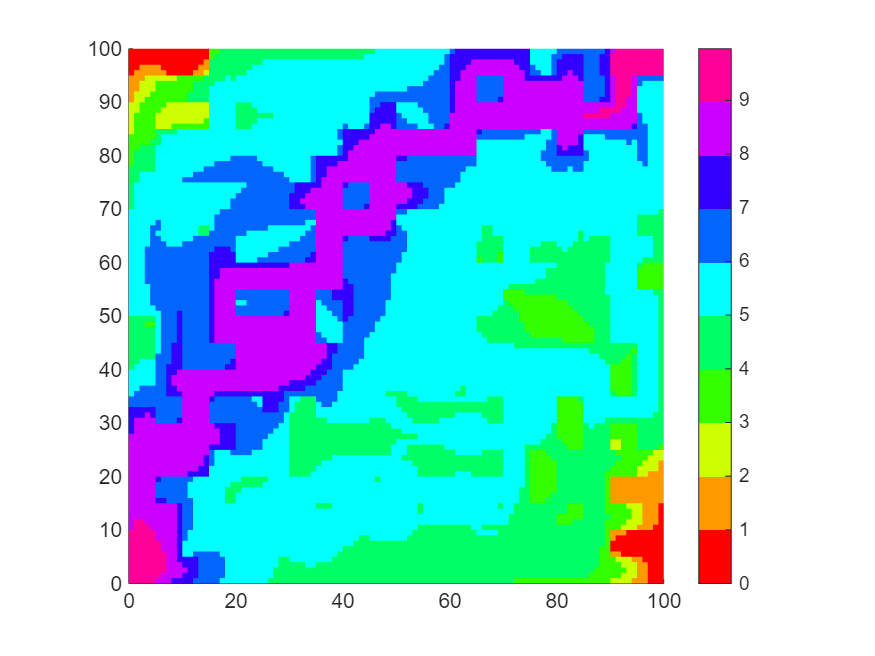

figure;
tt_index = -log10(ftt/min(ftt)) - log10(btt/min(btt));  % calculate travel time index
tt_index = tt_index - min(tt_index);                    % scale the variable to be >= 0
t_tt_index=tt_index; t_tt_index(t_tt_index > 10) = nan; % truncate values above 10
colormap(hsv(10));                                      % use 10 colors from hsv colormap
plotCellData(G2D,t_tt_index,'EdgeColor','none');        % plot the travel time index
colorbar;                                               % show the colorbar
axis equal tight;                                       % fit axes to limits + x/y aspect ratio at 1

This plot indicates that the variability in residence time spans 10 orders of magnitude within the aquifer. 

## Discussion 

In summary, this analysis demonstrates the complex nature of groundwater flow and residence times within a heterogeneous aquifer system. The simulations reveal that the fastest flow paths between the injection and pumping wells are predominantly through diagonally oriented channels, with varying residence times that highlight the influence of hydraulic conductivity contrasts. While particle tracking provides valuable insights into flow dynamics, it also has limitations, particularly in providing a comprehensive view of travel times throughout the aquifer.

The use of iso-contours and a log10 transformation of residence times further enhances our understanding by visualizing the extensive range of travel times, which can span 10 orders of magnitude. This variability underscores the importance of considering both local and regional scales when assessing aquifer behavior. Additionally, the scaled index introduced in [[2](https://www.researchgate.net/publication/331903631_Automatic_Generation_of_Locally_Refined_Composite_Grids_for_Efficient_Solute_Transport_Modeling)] proves useful for identifying aquifer regions and aiding in tasks such as visualization and efficient modeling of solute transport.

Overall, these findings emphasize the need for other approaches, like the Double Delineation Approach (DDA), to effectively capture the complexity of groundwater flow fields. As we move towards field-scale applications, the insights gained from this study can inform better management practices for groundwater resources, highlighting the critical role of understanding flow connectivity and residence time distributions in aquifer systems.

## References 

[1] [Sbai, M.A. (2018). A Practical Grid-Based Alternative Method to Advective Particle Tracking. Groundwater, 56(6), 881-892. https://doi.org/10.1111/gwat.12646](https://www.researchgate.net/publication/323339565_A_Practical_Grid-Based_Alternative_Method_to_Advective_Particle_Tracking)

[2] [Sbai, M.A. (2020). Automatic Generation of Locally Refined Composite Grids for Efficient Solute Transport Modeling. Groundwater, 58(1), 35-45. https://doi.org/10.1111/gwat.12882](https://www.researchgate.net/publication/331903631_Automatic_Generation_of_Locally_Refined_Composite_Grids_for_Efficient_Solute_Transport_Modeling)

Author: M.A. Sbai, Ph.D.

Copyright (C) 2024 Mohammed Adil Sbai

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.